# This is the main file for the reduced order modeling method for Stokes' equation

## Read in the data

N = 0:31;               %which samples?
[X, P, U, C] = readData(N);


## plot finescale data

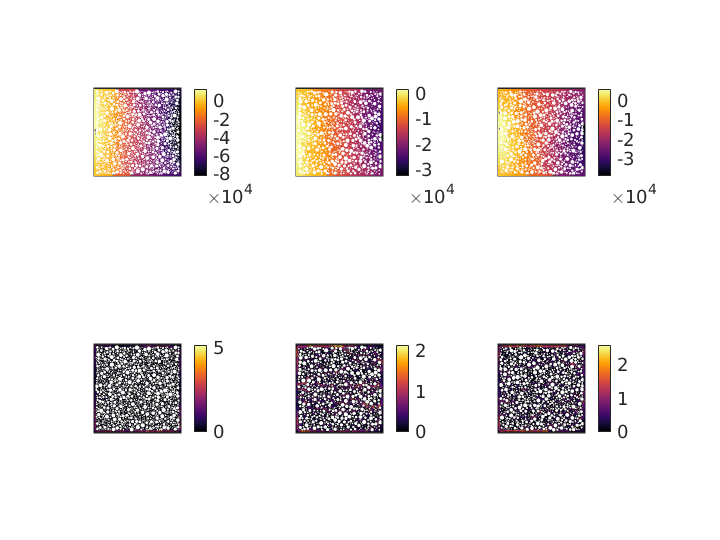

plt = true;
if plt
    figure
    n_low = 12;  %defines the samples to plot
    for i = 1:3
        n = n_low + i - 1;
        %pressure field
        spp = subplot(2, 3, i);
        tsp = trisurf(C{n}, X{n}(:, 1), X{n}(:, 2), P{n});
        tsp.LineStyle = 'none';
        axis square;
        view(2);
        grid off;
        box on;
        xticks({});
        yticks({});
        cbp = colorbar;
        
        %velocity field (norm)
        u_norm = sqrt(sum(U{n}.^2));
        spu = subplot(2, 3, i + 3);
        tsu = trisurf(C{n}, X{n}(:, 1), X{n}(:, 2), u_norm);
        tsu.LineStyle = 'none';
        axis square;
        view(2);
        grid off;
        box on;
        xticks({});
        yticks({});
        cbu = colorbar;
    end
end